# Identificazione in presenza di limitazioni di velocità/posizione massima.

Spesso i sistemi meccanici hanno limiti di posizione e velocità massima.

In questo caso, è necessario lavorare con range  positivi e negativi.

Tuttavia la presenza dell'attrito statico rende l'approssimazione lineare molto imprecisa quando si lavora con continui cambi di posizione e velocità.

## Esempio

consideriamo il modello meccanico motore-trasmissione-carico, con trasmissione elastica e presenza di attrito statico.

Il sistema ha un ingresso (la coppia motore), e due uscite (posizione e velocità motore). Ci interessa trovare un modello lineare che approssima la relazione coppia-velocità.

clc;clear all;close all;
set(0, 'defaultFigurePosition',  [ 1440, 792, 2240, 1680]); % figure più grandi
st=1e-3;
model=ElasticTransmission(st); 
model.getInputNumber

ans = 1

model.getOutputNumber

ans = 2

cs=ControlledSystem(model);

t=(0:st:140)';

w0=1; %rad/s
w1=pi/st; %rad/s
control_action_identificazione = chirp(t,w0/2/pi,t(end),w1/2/pi, 'logarithmic');
ampliezza_identificazione=2;

Sommo i due segnali

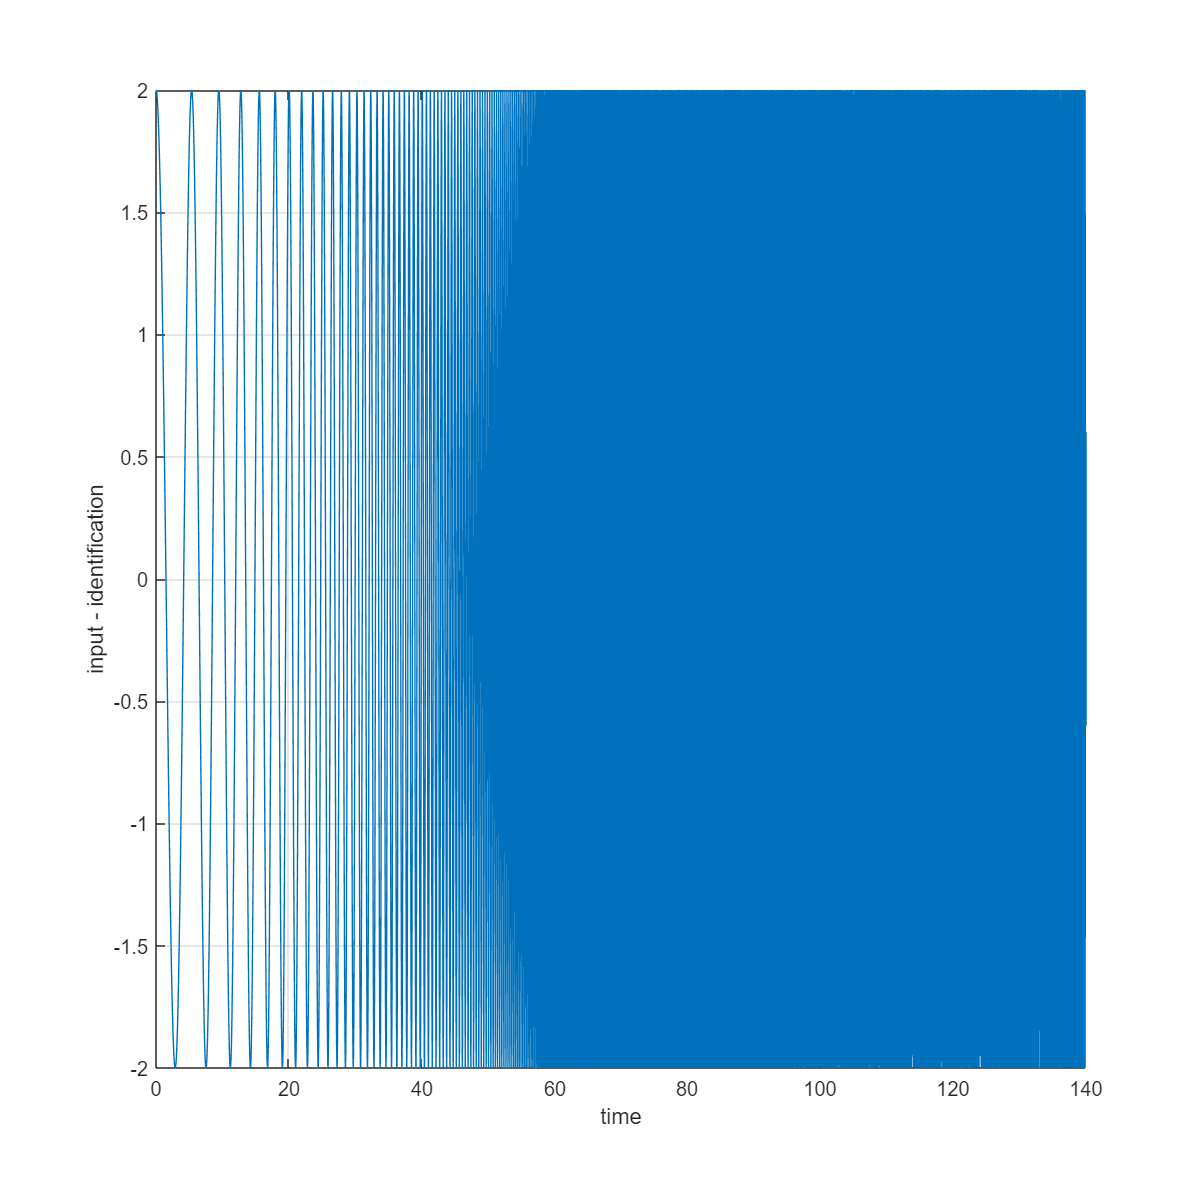

control_action=control_action_identificazione*ampliezza_identificazione;
figure
plot(t,control_action)
xlabel('time')
ylabel('input - identification')
grid on

## Simulazione sistema

for idx=1:length(t)
    [process_output(idx,:),t(idx,1)]=cs.openloop(control_action(idx));
end

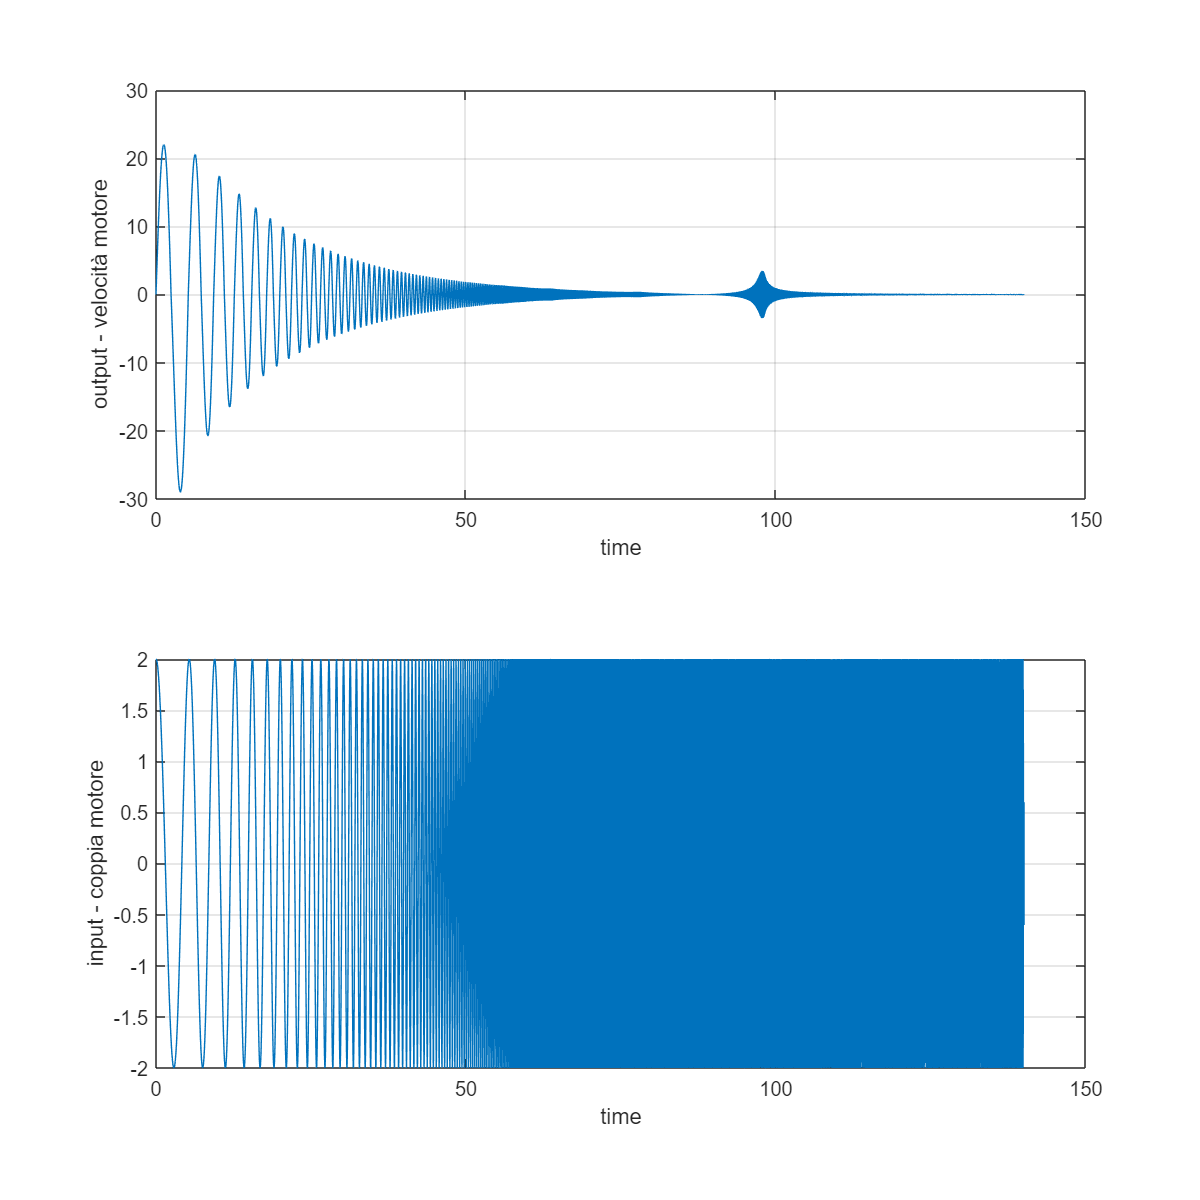

figure(1)
subplot(2,1,1)
plot(t,process_output(:,2))
xlabel('time')
ylabel('output - velocità motore')
grid on

subplot(2,1,2)
plot(t,control_action)
xlabel('time')
ylabel('input - coppia motore')
grid on

## Identificazione

### Calcolo risposta in frequenza

Definisco l'oggetto identification data (iddata)

identification=iddata(process_output(:,2),control_action,st);

Calcolo la risposta in frequenza con il comando e la plotto

freq_resp_ident = spafdr(identification);
figure(2)
bode(freq_resp_ident)

Plotto la frequenza di inizio del segnale eccitante

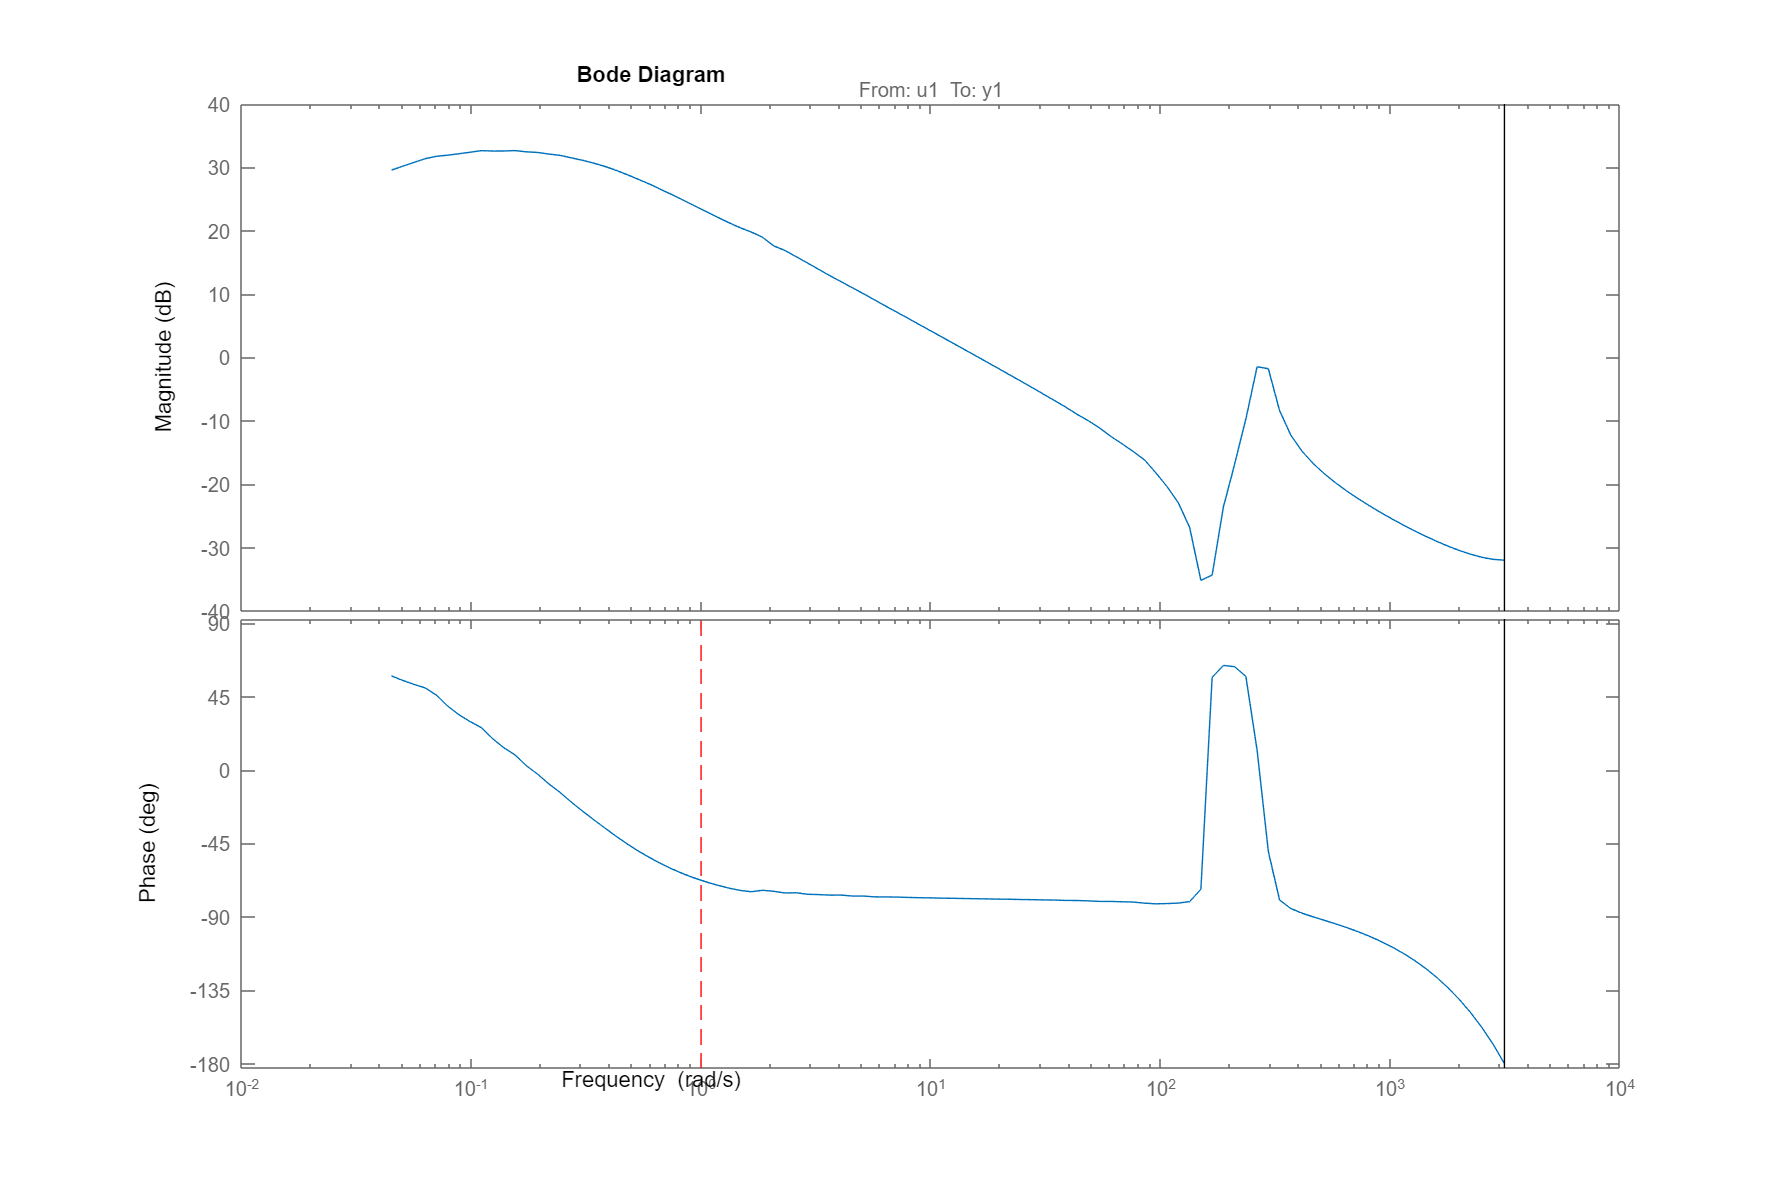

hold on
plot(w0*[1 1],ylim,'--r')
hold off

Nella parte a sinistra nella linea tratteggiata,il segnale non ha contribuito informatico apprezzabile ed è "disturbato" dalla presenza dell'attrito statico.

### Stima del modello

modello_continuo = ssest(freq_resp_ident,3);
modello_discreto = ssest(freq_resp_ident,3,'Ts',st);

### Grafico modelli

aggiungo opzione per evitare la molteplicità di 360° nella base

figure(3)
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';

plotto i dati sperimentali

h=bodeplot(freq_resp_ident, bode_opts);

si può aggiungere l'interfavollo di confidenza (in questo caso 3*sigma)

hold on
showConfidence(h,3)

grafico i modelli stimati

bode(modello_continuo,modello_discreto, bode_opts)

hold off

legend('Identification','Modello continuo','Modello discreto')

## Identificazione modello con peso sulle frequenza

Il modello si concentra 